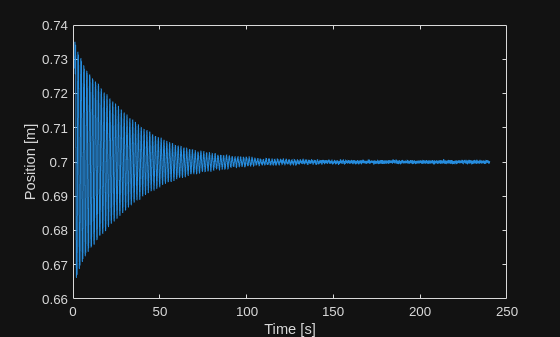

clc; clear; close all;
load test_trj1_copy_NO_SHAPER_240s.mat
Tc= 0.001; %s
tempo_inizio = 1;%s
tempo_fine = tempo_inizio + 239;
%Per scartare dati rumorosi
indice_inizio = tempo_inizio* 1/Tc;
indice_fine = tempo_fine* 1/Tc;
time = time(indice_inizio:indice_fine);
joint_position = joint_position(indice_inizio:indice_fine);
plot(time, joint_position)
xlabel("Time [s]")
ylabel("Position [m]")

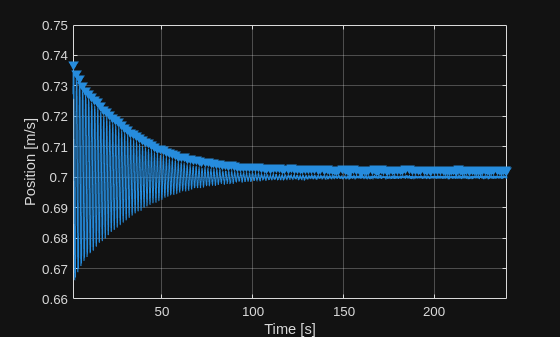

[pks,locs] = findpeaks(joint_position,time, MinPeakDistance=1);
findpeaks(joint_position,time, MinPeakDistance=1)
xlabel("Time [s]")
ylabel("Position [m/s]")

xi = 1/sqrt( 1+( (2*pi) / (log (pks(20)/pks(21)) ))^2)

xi = 9.6312e-05

delta = log (pks(20)/pks(21))

delta = 6.0515e-04

xi = 2*delta*sqrt(1/4 * delta^2 + pi^2)/(delta^2+4*pi^2)

xi = 9.6312e-05

omega_d = 2*pi/(locs(21)-locs(20))

omega_d = 3.8833


res = [];
for i=1:length(locs)-1
    res = [res;2*pi/(locs(i+1)-locs(i))];
end
Td = mean(diff(locs))

Td = 1.4746

omega_d=mean(res)

omega_d = 4.4456

res = [];
for i=1:length(locs)-1
    res = [res;1/sqrt( 1+( (2*pi) / (log (pks(i)/pks(i+1)) ))^2)];

end
xi = mean(res)

xi = 7.4790e-05